# **Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clearvars
close all
clear all;clc
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 3 PRIOR DISTRIBUTION OF THE MODEL PARAMETERS



PriorOpts.Marginals(1).Name = 'E'; % Young's modulus
PriorOpts.Marginals(1).Type = 'Lognormal';
PriorOpts.Marginals(1).Moments = [30 4.5]*1e9 ; % (N/m^2)

PriorOpts.Marginals(2).Name = 'p'; % uniform load
PriorOpts.Marginals(2).Type = 'Lognormal';
PriorOpts.Marginals(2).Moments = [12e3 3e3]; % (N/m)

PriorOpts.Marginals(3).Name = 'P'; % point load
PriorOpts.Marginals(3).Type = 'Lognormal';
PriorOpts.Marginals(3).Moments = [50e3 1e3] ; % (N)



PriorOpts.Marginals(4).Name = 'Sigma2_1';               % sigma2_1
PriorOpts.Marginals(4).Type = 'Uniform';
PriorOpts.Marginals(4).Parameters  = [0 1e-6];



PriorOpts.Marginals(5).Name = 'Sigma2_1';               % sigma2_1
PriorOpts.Marginals(5).Type = 'Uniform';
PriorOpts.Marginals(5).Parameters  = [0 1e-10];

myPriorDist = uq_createInput(PriorOpts);

## 5 - Loglikelihood

Measurement_All = [12.84; 13.12; 12.13; 12.19; 12.67;0.235; 0.236; 0.229]/1000;
myData.y = Measurement_All;
size(myData.y)

ans =      8     1


myData.Name = 'Measurement on 29 points along the beam';
myLogLikeli = @(params,y)  LL1(params,y(1:5,:))   + LL2(params,y(6:8,:));

## 6 -  BAYESIAN ANALYSIS


Starting AIES...

|##                            |   5.00%|###                           |  10.00%|#####                         |  15.00%|######                        |  20.00%|########                      |  25.00%|#########                     |  30.00%|###########                   |  35.00%|############                  |  40.00%|##############                |  45.00%|###############               |  50.00%|#################             |  55.00%|##################            |  60.00%|####################          |  65.00%|#####################         |  70.00%|#######################       |  75.00%|########################      |  80.00%|##########################    |  85.00%|###########################   |  90.00%|############################# |  95.00%|##############################| 100.00%


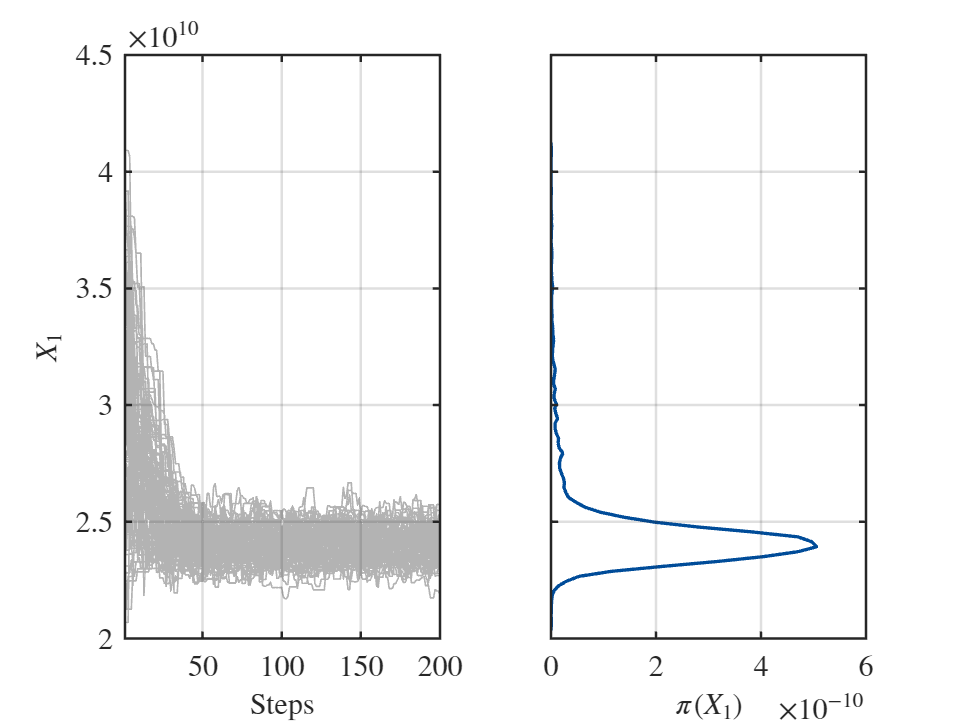

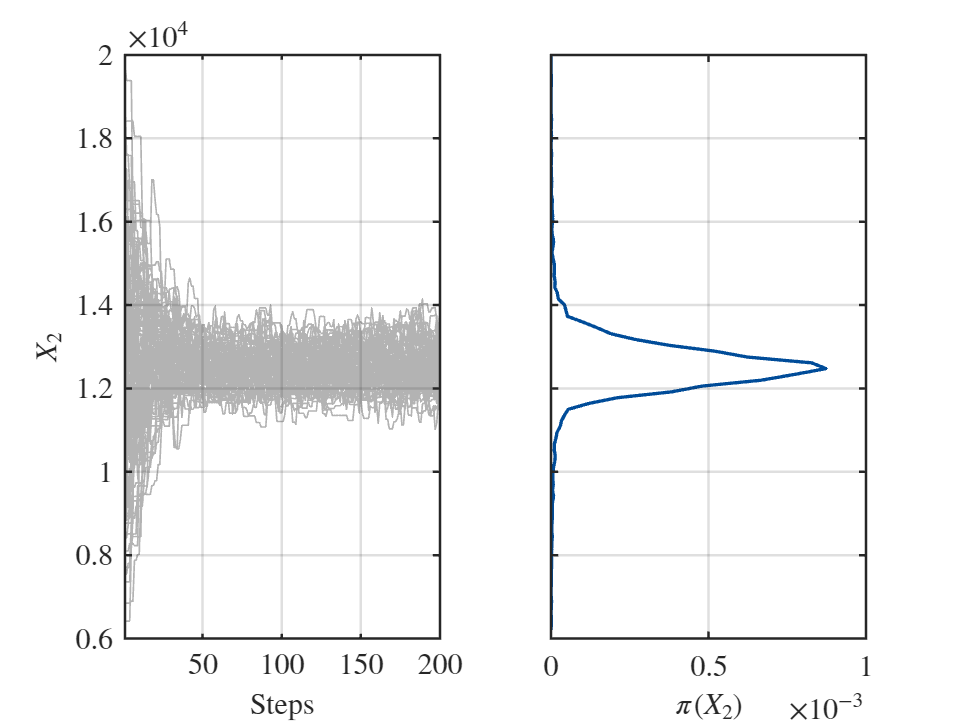

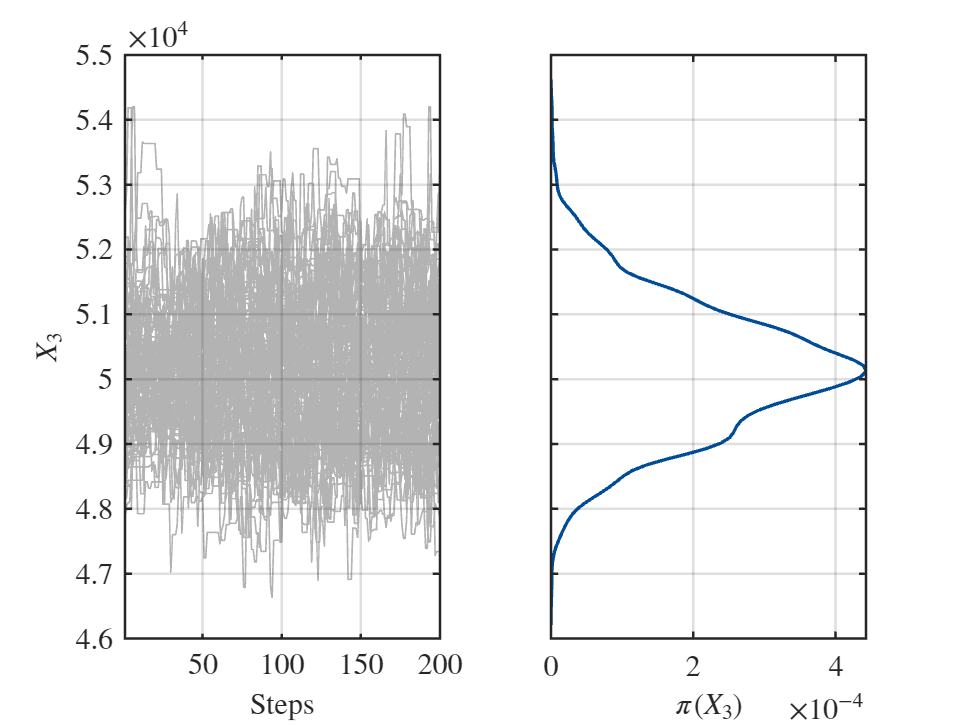

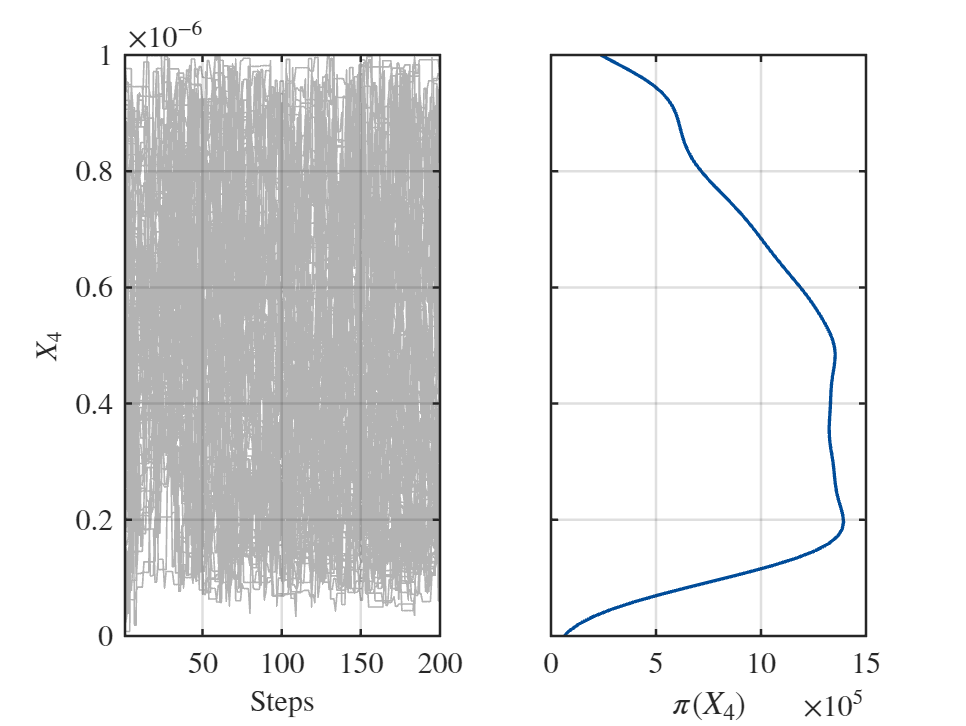


Finished AIES!



Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2 3 4];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 200;
Solver.MCMC.NChains = 100;
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

uq_print(BayesAnalysis)

%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:05
   Number of sample points:                       2.00e+04

%------------------- Posterior Marginals
---------------------------------------------------------------
| Parameter | Mean    | Std     | (0.025-0.97) Quant. | Type  |
---------------------------------------------------------------
| E         | 2.4e+10 | 6.5e+08 | (2.3e+10 - 2.5e+10) | Model |
| p         | 1.3e+04 | 4.4e+02 | (1.2e+04 - 1.3e+04) | Model |
| P         | 5e+04   | 1.1e+03 | (4.8e+04 - 5.2e+04) | Model |
| Sigma2_1  | 4.3e-07 | 2.5e-07 | (9.2e-08 - 9.5e-07) | Model |
| Sigma2_1  | 4.5e-11 | 2.6e-11 | (7.1e-12 - 9.6e-11) | Model |
---------------------------------------------------------------

%------------------- P

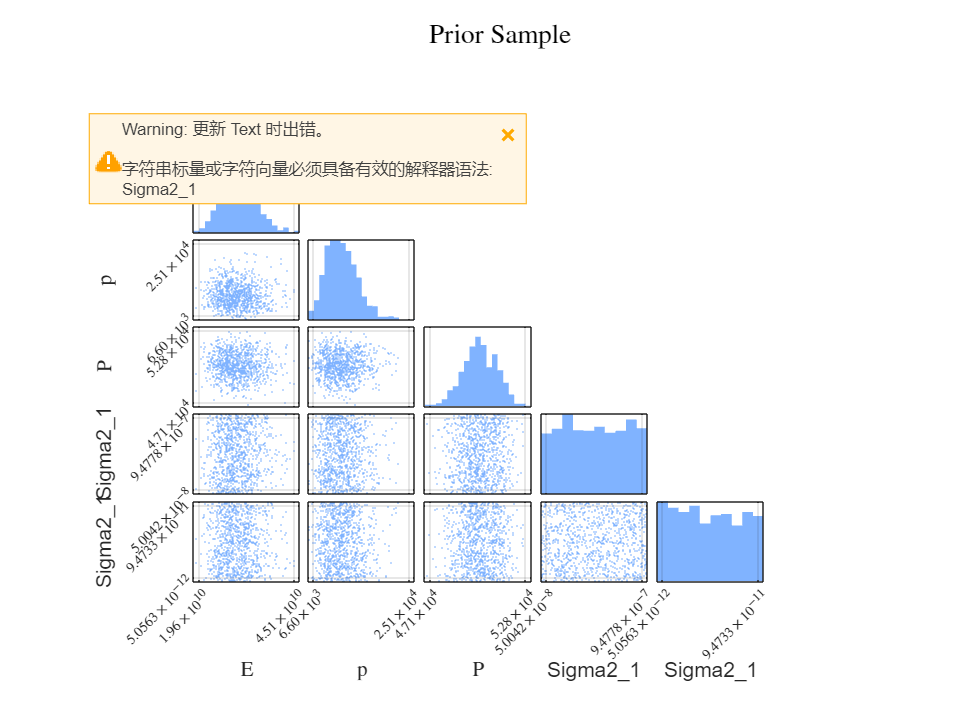

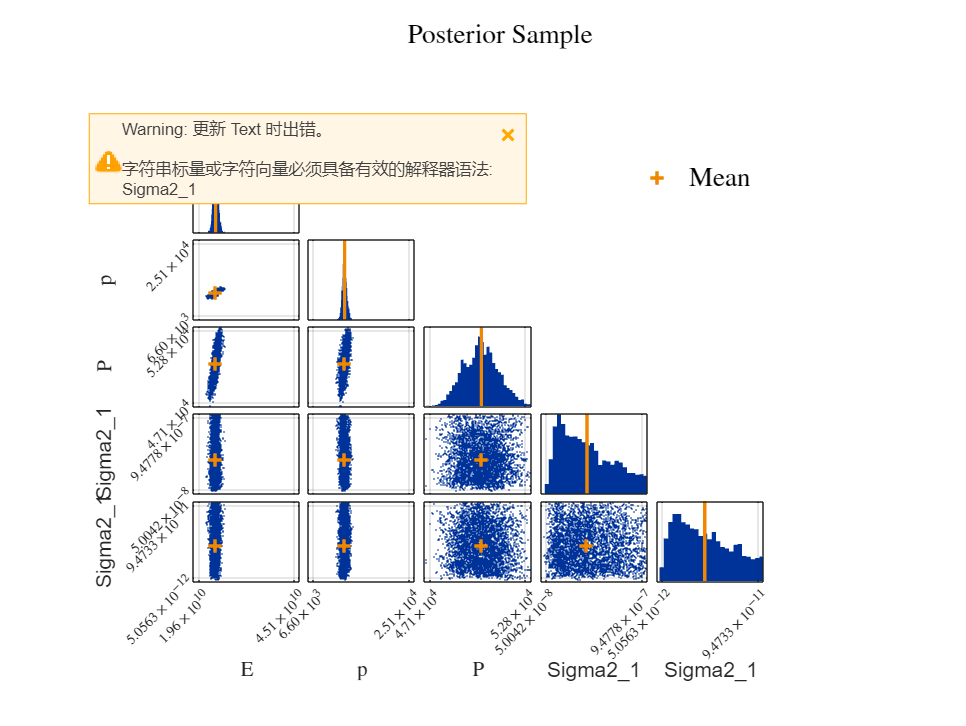

uq_display(BayesAnalysis)